clear

% Read img file
img = imread("../db/DB1/db1_12.jpg")

img = 552×622×3 uint8 array
img(:,:,1) =

   198   197   198   200   201   201   201   202   200   200   200   200   200   201   201   201   202   202   201   201   202   202   203   203   202   200   200   203   205   204   204   205   204   202   203   204   204   202   205   211   207   205   204   204   203   200   199   200   202   204   205   205   203   203   204   205   204   208   208   206   206   206   206   208   207   209   210   210   210   210   209   209   207   207   207   208   209   210   211   212   211   209   207   208   211   212   212   211   212   212   212   212   211   211   211   211   214   212   215   212   216   212   214   211   212   213   213   214   214   214   213   212   213   212   212   211   212   212   212   212   214   215   215   216   216   216   217   217   214   214   214   214   214   215   215   215   215   215   215   216   217   217   218   218   217   216   216   216   216   217   217   217   217   217   217   217   218   218   219   2

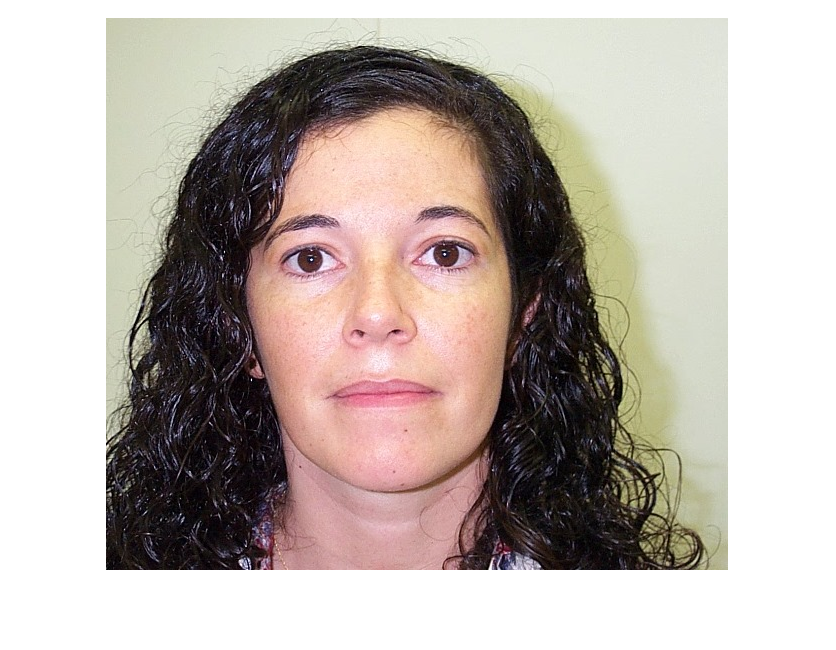

imshow(img)

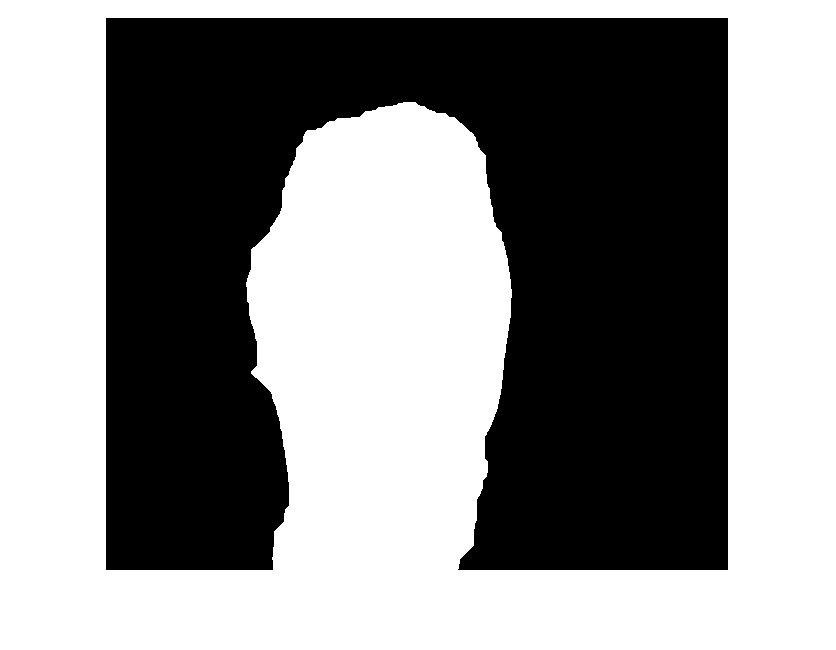

% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)


%Find eyes and a mouth
eyes = eyemap(img_gw)

eyes =     0.0615    0.0615    0.0615    0.0610    0.0615    0.0615    0.0615    0.0615    0.0625    0.0625    0.0622    0.0619    0.0619    0.0622    0.0622    0.0619    0.0619    0.0619    0.0619    0.0619    0.0626    0.0626    0.0626    0.0626    0.0626    0.0626    0.0626    0.0626    0.0631    0.0626    0.0639    0.0644    0.0639    0.0639    0.0639    0.0639    0.0639    0.0639    0.0639    0.0639    0.0639    0.0639    0.0636    0.0636    0.0630    0.0635    0.0635    0.0635    0.0630    0.0633
    0.0615    0.0615    0.0610    0.0615    0.0615    0.0615    0.0615    0.0615    0.0625    0.0625    0.0623    0.0623    0.0622    0.0626    0.0622    0.0619    0.0619    0.0619    0.0619    0.0619    0.0626    0.0626    0.0626    0.0626    0.0631    0.0626    0.0626    0.0626    0.0626    0.0626    0.0639    0.0639    0.0639    0.0639    0.0639    0.0644    0.0644    0.0639    0.0634    0.0639    0.0639    0.0639    0.0636    0.0636    0.0636    0.0636    0.0636    0.0636    0.0630  

eye_mask = eyemask((eyes),face_mask)

eye_mask = 552×622 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

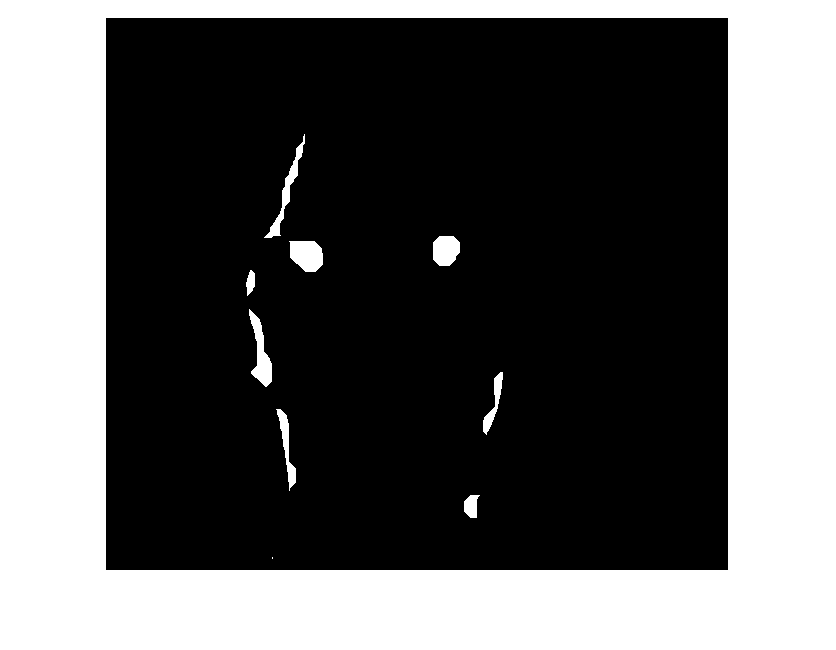



imshow(eye_mask);


mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)

[x,y] = mouth_index(mouth_mask)

x = 278.8822

y = 377.4364

[indexX,indexY] = eye_index(eye_mask)

indexX =   201.3606  340.3382  365.8902


indexY =   237.6797  232.8779  488.7348



% eye_centers = cat(length(indexX),x,y);
%----------------------------------------%
% Calculate the center of the mouth (you might need to adjust this based on your specific case)
mouth_center = [x, y]; % replace with actual coordinates

% Calculate the distance of each eye center from the mouth center
eye_centers = [indexX(:) + indexY(:)/2, indexY(:)];
distances = sqrt(sum((eye_centers - mouth_center).^2, 2));

% Find the indices of the two eyes with the closest distance to the mouth
%[~, sorted_indices] = sort(distances)
%closest_eye_indices = sorted_indices(1:2)
%closest_eyes = [indexX(closest_eye_indices), indexY(closest_eye_indices)]

% Beräkna avståndet mellan varje öga och ansiktets mitt
face_mid = [size(img, 2) / 2, size(img, 1) / 2]; % Mitt av ansiktet
eye_distances_to_mid = sqrt((indexX - face_mid(1)).^2 + (indexY - face_mid(2)).^2);

% Sortera ögonen baserat på avståndet till ansiktets mitt
[sorted_mid_distances, sorted_mid_indices] = sort(eye_distances_to_mid)

sorted_mid_distances =    52.1560  116.1432  219.7022


sorted_mid_indices =      2     1     3



% Välj de två ögonen som är närmast ansiktets mitt
closest_mid_eye_indices = sorted_mid_indices(1:2)

closest_mid_eye_indices =      2     1


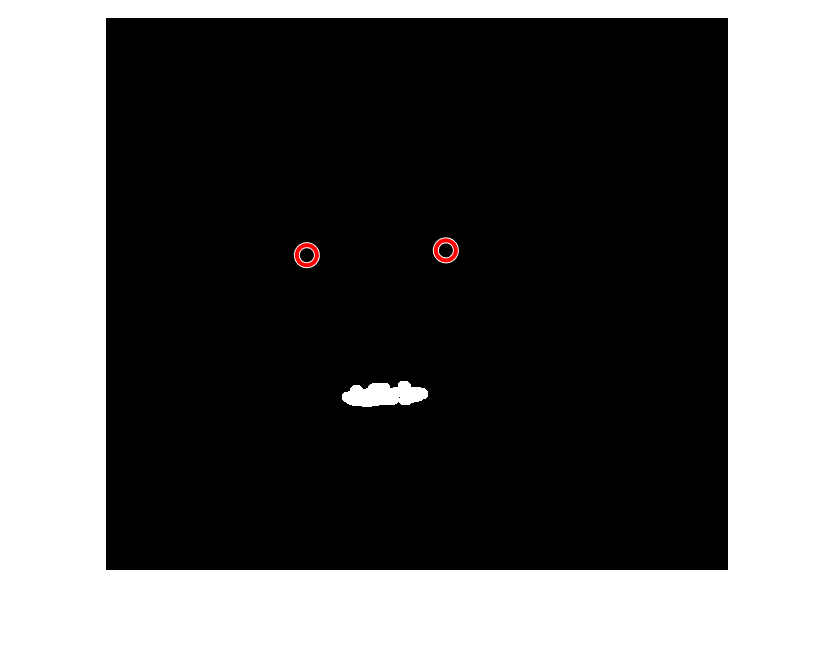

closest_mid_eyes = [indexX(closest_mid_eye_indices), indexY(closest_mid_eye_indices)];

%test

% Visualization
viscircles([closest_mid_eyes(1), closest_mid_eyes(3)], 10);
viscircles([closest_mid_eyes(2), closest_mid_eyes(4)], 10);

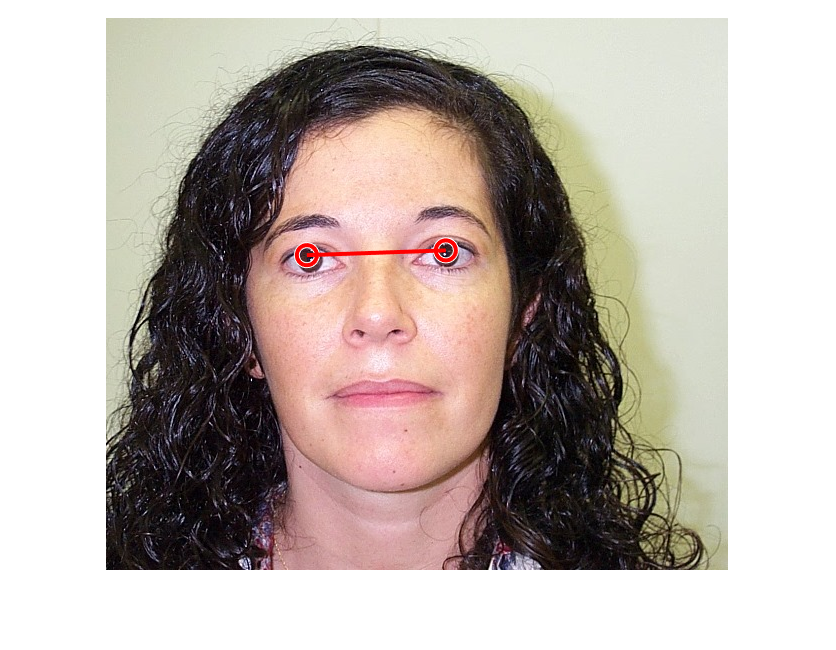


eye1 = [closest_mid_eyes(1), closest_mid_eyes(3)];
eye2 = [closest_mid_eyes(2), closest_mid_eyes(4)];


figure;
imshow(img);
hold on;
viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r')

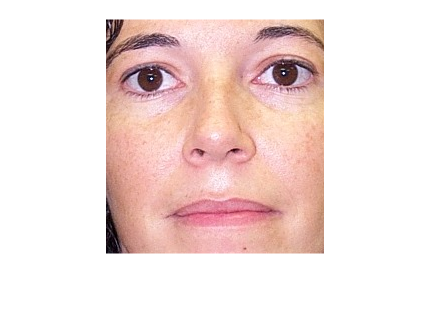


% Definiera antal pixlar från munnen neråt, ögonen uppåt, samt ögonen utåt
pixels_down_from_eyes = 180; % Antal pixlar från munnen neråt
pixels_up_from_eyes = 50;    % Antal pixlar från ögonen uppåt
pixels_sideways_from_eyes = 40; % Antal pixlar från ögonen utåt

% Beräkna koordinaterna för den nya rektangeln som inkluderar ansiktet
xmin = min([eye1(1), eye2(1)]) - pixels_sideways_from_eyes;
ymin = min([eye1(2), eye2(2)]) - pixels_up_from_eyes;
width = max([eye1(1), eye2(1)]) - xmin + pixels_sideways_from_eyes;
height = max([mouth(2), eye1(2), eye2(2)]) - ymin + pixels_down_from_eyes;

% Säkerställ att det inte går utanför bildens gränser
xmin = max(1, xmin);
ymin = max(1, ymin);
width = min(size(img, 2) - xmin + 1, width);
height = min(size(img, 1) - ymin + 1, height);

% Avrunda koordinaterna för att säkerställa att de är heltal
xmin = round(xmin);
ymin = round(ymin);
width = round(width);
height = round(height);

% Beskär bilden baserat på de beräknade koordinaterna
cropped_img = img(ymin:ymin+height-1, xmin:xmin+width-1, :);

% Visa den beskurna bilden
figure;
imshow(cropped_img)

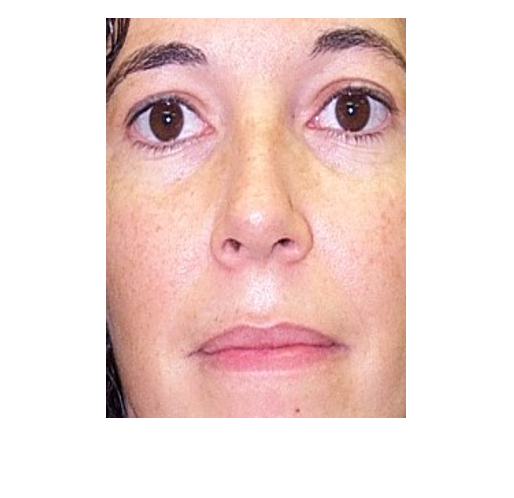


% Definiera önskad storlek för alla beskurna bilder
desired_height = 400;
desired_width = 300;

% Ändra storleken på den beskurna bilden till önskad storlek
resized_img = imresize(cropped_img, [desired_height, desired_width]);

% Visa den ändrade bilden till önskad storlek
figure;
imshow(resized_img);